% % Find eyes 
% C1 = imread('../db/DB0/db0_1.jpg');
% imshow(C1)
% 
% SE = strel('disk',3);
% IM2 = imopen(C1, SE);
% IM3 = imclose(IM2, SE);
% %disp(SE.Neighborhood)
% imshow(IM3)
% 
% %10
% SE2 = strel('line',6,0);
% IM4 = imopen(IM3, SE2);
% IM5 = imclose(IM4, SE2);
% imshow(IM5)


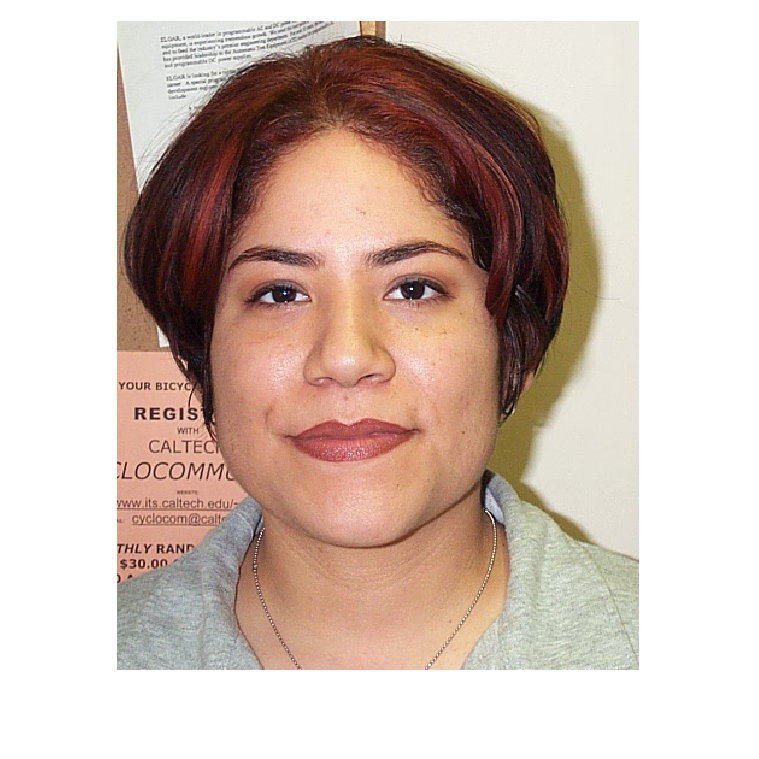

C1 = imread('../TNM034/Facial-recognition/db/DB0/db0_1.jpg');
imshow(C1)

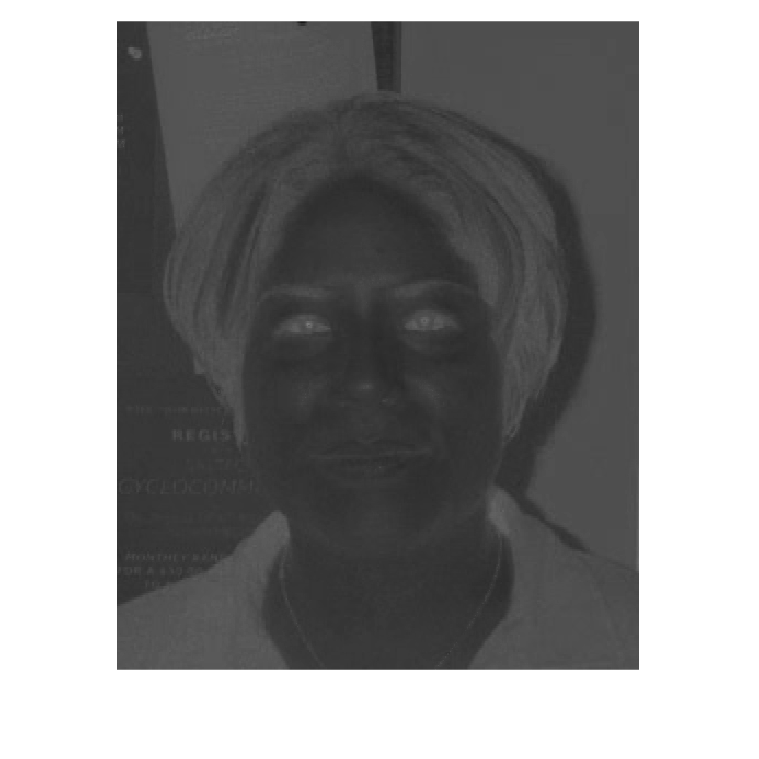

C2 = rgb2ycbcr(C1);
imshow(C2)

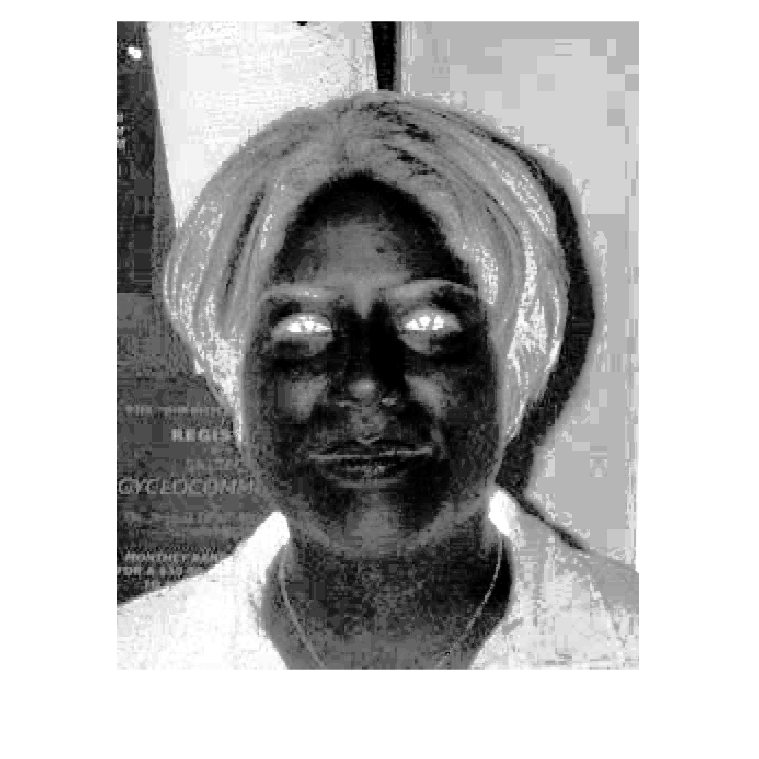

C3 = double(C2);
imshow(C3,[])

y=C3(:,:,1);
cb=C3(:,:,2);
cr=C3(:,:,3);
ccb=cb.^2;
imshow(ccb,[]);

ccr=(1-cr).^2;
imshow(ccr,[]);

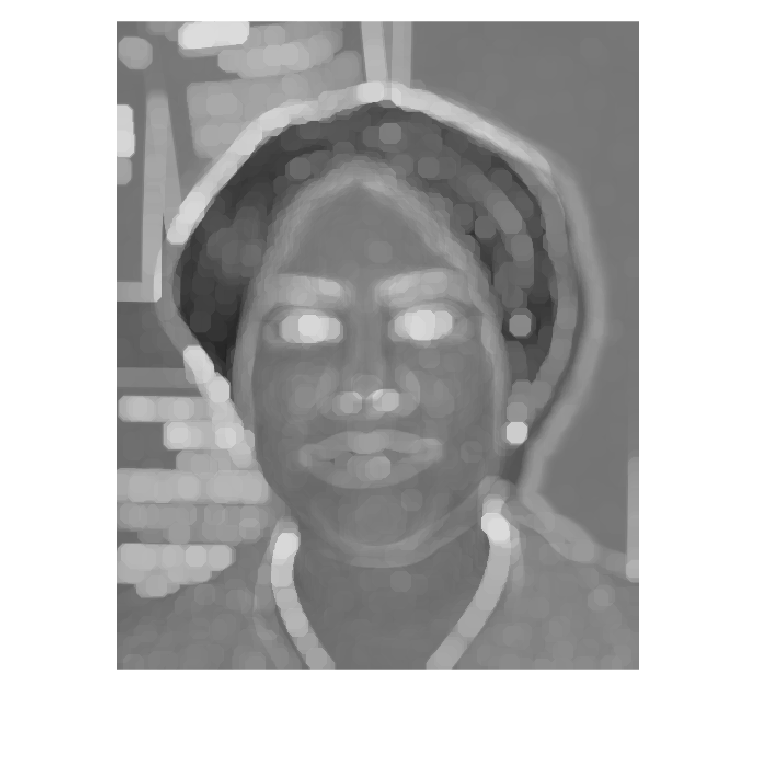


cbcr=ccb./cr;
imshow(cbcr,[]);

%EyemapC
EyemapC=(ccb+ccr+cbcr)/3;
imshow(EyemapC,[])

%Histogram equalization
C6=histeq(EyemapC);
imshow(C6,[])

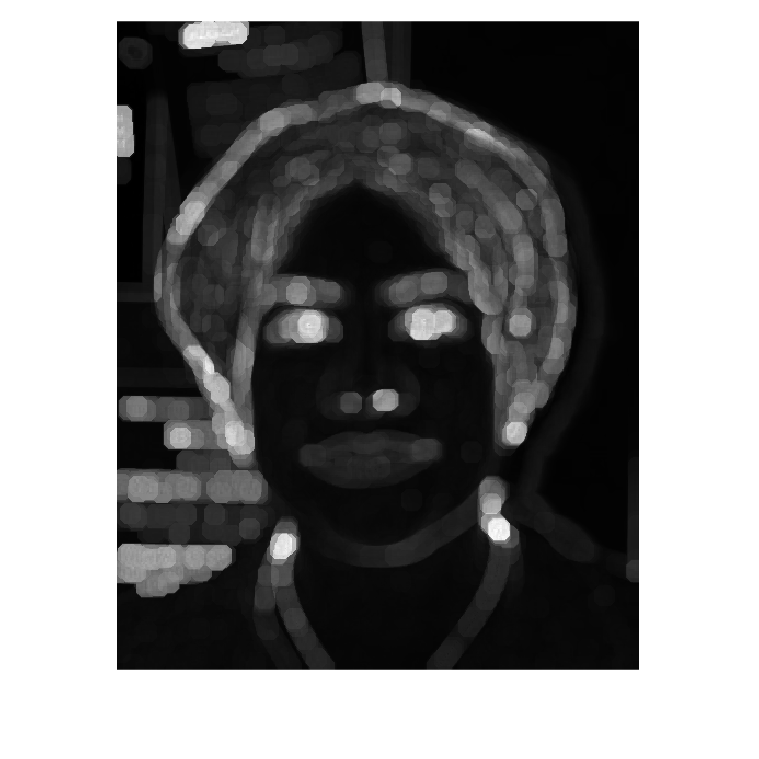


%EyemapL
SE=strel('disk',10);
o=imdilate(y,SE);
p=1+imerode(y,SE);
EyemapL=o./p;
imshow(EyemapL, []);

%Eyemap
Eyemap = EyemapC.*EyemapL;
imshow(Eyemap,[]);

%Dilated & masked
C8 = strel(10);
result = imdilate(Eyemap,C8);
imshow(result,[]);

%Normalizing
result = (result./max(result(:)));
imshow(result,[]);

%imwrite(result,'../TNM034/Facial-recognition/db/DB0/eyedetection/db0test2.png')